# 2D Mie Scattering

[**Mie scattering**](https://en.wikipedia.org/wiki/Mie_scattering) (also know as Mie solution) describes the scattering of an electromagnetic plane wave by a homogeneous sphere. The solution takes the form of an infinite series of spherical multipole partial waves.

In this example, we show the Mie scattering field of a homogenious 2D cylinder (infinite along $z$) with planar incident wave. All materials in the simulation are assumed to be linear, homogeneous, and isotropic (LHI).

### Step 0: Global settings

The simulation begins with the initialization of a `Model2D` instance, followed by defining the global settings.  The working plane is set to the $\mathit{\mathbf{x}}-\mathit{\mathbf{y}}$** plane** as default. The background is designed as air, which is the defualt setting of background.

modelC = Model2D.initialize();

Model2D: Object Reset and Initialized


### Step 1: Set up the cylindrical scatterer

#### 1.1 Geometry parameters

The radius of the cylinder is set to be **0.6** **µm, **while the center is located at (0,0).

% geometry parameters [unit: m]
radius = 0.6e-6;
position = [0, 0]; % [x, y]

#### 1.2 Material information

The cylinder is made of **fused silica** while the surrounding enviroment is **air**. At $\lambda =0\ldotp 8$**µm**, the refractive indices are $n_{FS} = 1.4533$.

% material
eps_fs = 1.4533^2; % Fused silica

#### 1.3 Construct simulation device

Construct the entire simulation device by creating each of them (air enviroment and silicon cylinder) individually and combining them together.

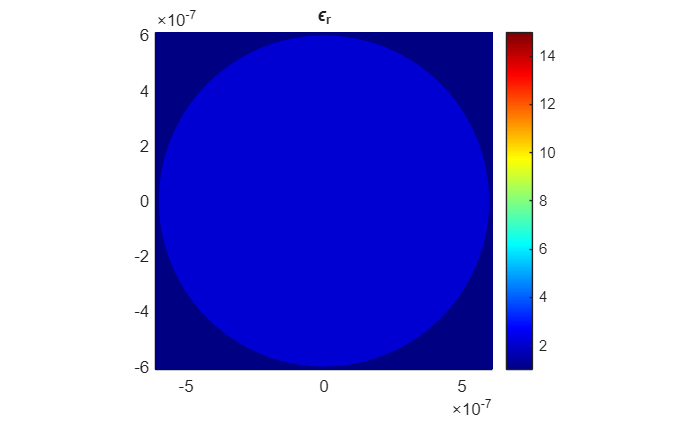

% build cylinder
modelC.addDevice(1);
modelC.setDevice(1).setGeometry('Disk', radius, position);
modelC.setDevice(1).setMaterial(eps_fs);

% complete device
modelC.assembleDevice;
modelC.device.dispImg;

### Step 2: FDFD region mesh grid

The FDFD solver operates on a uniform mesh grid to discretize the simulation domain. Before meshing, the geometry is represented as a `polyshape` object. After meshing, it transforms into a discrete double array that captures the spatial distribution of relative permittivity $\varepsilon_r$ and relative permeability $\mu_r$.

The FDFD region is set in the $x-y$ plane with grid sizes ${\rm d}x = {\rm d}y = 30 {\rm nm}$.

% mesh grid
Nx = 401; dx = 30e-9;
Ny = 401; dy = 30e-9;
modelC.setMesh([Nx, Ny], [dx, dy]);

% mesh device
modelC.meshDevice;

### Step 3: Set up FDFD solver

The simulation is performed for the wavelength of **800 nm**. 

modelC.setWavelength(0.8e-6);
modelC.setSolver("Scattering", 'TE'); % choose 'Scattering' solver and set polarization as TE
modelC.setBoundary('x', 'PML', 10); % PML boundary condition for both x and y boundaries
modelC.setBoundary('y', 'PML', 10);

### Step 4: Add port

The port must be defined inside the FDFD region. For this example, we show the case of injecting source aling $y$ axis. 

modelC.addPort('+y', -4e-6, [-6e-6, 6e-6]);

**Note**: Even though port is supposed to be as wide as possible to simulate plane-wave situation,  it shouldn't be overlapped within PML region. Be careful when setting the size of port.

### Step 5: Set input source

Mie scattering discusses theoretical solution of scattering with plane-wave injection. Therefore, we set the source type as TE mode '`PlaneWave'`. 

% plane wave
modelC.addSource('PlaneWave');
theta = 0; 
modelC.setSource.setAngle(theta); % rotate source

### Step 6: Launch 2D scattering simulation

Before simulating the scattering field, make the device is fully meshed, and the input source properly configured. Then call method `'solveModel'` in `model `object to launch solver. 

modelC.dispInfo;

=== Model2D Information ===
Wavelength   : 8.000e-07 m
Plane Label  : xy
Background   : eps_r=1.000, mu_r=1.000
Mesh         : x: N=401, d=3.000e-08 m
               y: N=401, d=3.000e-08 m
Solver       : Scattering
BC (x)     : PML, thickness=10
BC (y)     : PML, thickness=10
Source Polarization : TE
Source Port         : dir=+y
                      position (y) = -4.000e-06 m
                      span (x)     = [-6.000e-06, 6.000e-06] m


modelC.solveModel;

Model object has been solved successfully.


When the solving is completed, we can export simulation results and visulize them.

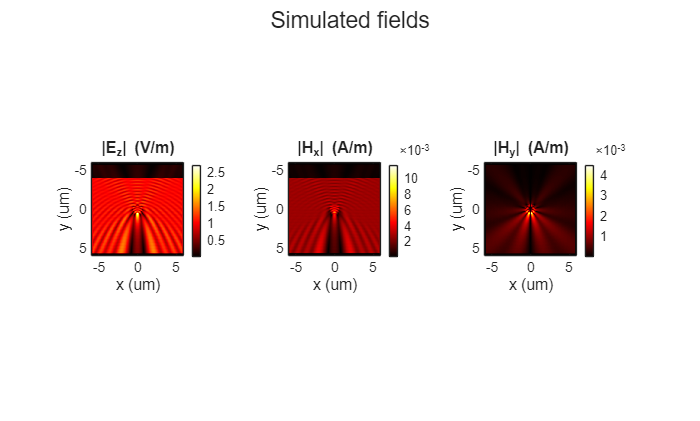

results = modelC.exportResults;

figure; sgtitle('Simulated fields')
subplot(1,3,1);
imagesc(results.x*1e6, results.y*1e6, abs(results.Ez).');
xlabel('x (um)'), ylabel('y (um)'); axis image;
title('|E_z| (V/m)');
colormap hot; colorbar;
subplot(1,3,2);
imagesc(results.x*1e6, results.y*1e6, abs(results.Hx).');
xlabel('x (um)'), ylabel('y (um)'); axis image;
title('|H_x| (A/m)');
colormap hot; colorbar;
subplot(1,3,3);
imagesc(results.x*1e6, results.y*1e6, abs(results.Hy).');
xlabel('x (um)'), ylabel('y (um)'); axis image;
title('|H_y| (A/m)');
colormap hot; colorbar;